# RESULT: Arm Design Comparison

*MATLAB Version:*

version

ans = '24.1.0.2689473 (R2024a) Update 6'

*Last revised:*

date

ans = '30-Oct-2024'

color_gray = [150 150 150] / 255;
color_light_gray = [175, 175, 175] / 255;

color_green = [45 182 125] / 255;
color_yellow = [100 143 255] / 255;
color_red = [255 48 150] / 255;
%color_blue = [100 143 255] / 255;
colors = [color_red; color_yellow; color_green];

% Lighter colors
color_light_green = [130 205 174] / 255;
color_light_yellow = [248 203 97] / 255;
color_light_blue = [135 167 250] / 255;
color_light_red = [230 100 164] / 255;

% Darker colors
color_dark_green = [0.0706    0.5137    0.3294];
color_dark_blue = [0.2941    0.4196    0.7490];
color_dark_yellow = [0.7490    0.5176         0];
color_dark_red = [0.6549    0.1059    0.3725];
colors_dark = [color_dark_red; color_dark_blue; color_dark_green];

% Define arm base curve
% First we define the arm's design
N_nodes = 6

N_nodes = 6


pose_base = [0; 0; -pi/2];
g_0 = Pose2.hat(pose_base);

rho_outer = 0.08;
rho_inner = 0.015;

rhos = [-rho_outer, -rho_inner, rho_inner, rho_outer];
mat_A = [
    1, 1, 1, 1;
    0, 0, 0, 0;
    -rhos;
    ];

f_bellow = @JacobBellowMechanics.actuator_force;
f_muscle = @GinaMuscleMechanics.actuatorForce_key;
fs = {f_bellow, f_muscle, f_muscle, f_bellow};

l_0 = 0.50;

p_bounds = [50; 100; 100; 50];

% Combine the design parameters into a struct
struct_design = struct();
struct_design.mat_A = mat_A;
struct_design.l_0 = l_0;
struct_design.fs = fs;
struct_design.g_0 = g_0;
struct_design.rhos = rhos;
struct_design.p_bounds = p_bounds;

tip_load = [0; -10; 0];

% Define the target shape
a = -1;
b = 1;

l = 0.5;

s = linspace(0, 1, N_nodes);
segment_twists = [
    l*ones(size(s));
    zeros(size(s));
    a*s + b
];

poses = calc_poses(g_0, segment_twists);

% Naively find the pressure which gets the arm closest to the target pose
%error("Warning: this block will take 30sec to run")
tic
[p_soln_min_pose_err, ~, poses_soln_min_pose_err] = find_p_minimize_pose_error(segment_twists, tip_load, struct_design, ones(1, N_nodes));


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


toc

Elapsed time is 17.979094 seconds.


tic
[~, p_soln_min_rxn_diff] = find_p_minimize_reaction_diff(segment_twists, tip_load, struct_design);
toc

Elapsed time is 2.116929 seconds.



twists_soln_min_rxn_diff = solve_equilibrium_shape(N_nodes, struct_design, p_soln_min_rxn_diff, tip_load);
poses_soln_min_rxn_diff = calc_poses(g_0, twists_soln_min_rxn_diff);

[closest_af_min_pose_err, closest_am_min_pose_err] = compute_reaction_traces(p_soln_min_pose_err, segment_twists, struct_design);
[closest_af_min_rxn_diff, closest_am_min_rxn_diff] = compute_reaction_traces(p_soln_min_rxn_diff, segment_twists, struct_design);

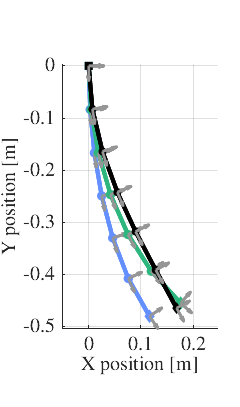

struct_closest_rxn_style = struct( ...
    "color", color_yellow, ...
    "markerfacecolor", color_yellow, ...
    "linestyle", "-", ...
    "linewidth", 3, ...
    "marker", "o", ...
    "markersize", 4, ...
    "markerindices", 2:N_nodes ...
);
struct_closest_pose_style = struct_closest_rxn_style;
struct_closest_pose_style.markerfacecolor = color_green;
struct_closest_pose_style.color= color_green;

fig_arm = figure("Visible", "on", "Position", [0, 0, 250, 400], "Color", "w");
ax = axes(fig_arm);
plot_poses(poses_soln_min_rxn_diff, ax, struct_closest_rxn_style, true, "axis_length", 0.15, "pose_markers_colored", false);
struct_closest_rxn_style.marker="square";
struct_closest_rxn_style.markerindices=1;
plot_poses(poses_soln_min_rxn_diff, ax, struct_closest_rxn_style, true, "axis_length", 0.15, "pose_markers_colored", false);
struct_closest_rxn_style.marker="diamond";
struct_closest_rxn_style.markerindices=N_nodes+1;
plot_poses(poses_soln_min_rxn_diff, ax, struct_closest_rxn_style, true, "axis_length", 0.15, "pose_markers_colored", false);

plot_poses(poses_soln_min_pose_err, ax, struct_closest_pose_style, true, "axis_length", 0.15, "pose_markers_colored", false);
struct_closest_pose_style.marker="square";
struct_closest_pose_style.markerindices=1;
plot_poses(poses_soln_min_pose_err, ax, struct_closest_pose_style, true, "axis_length", 0.15, "pose_markers_colored", false);
struct_closest_pose_style.marker="diamond";
struct_closest_pose_style.markerindices=N_nodes+1;
plot_poses(poses_soln_min_pose_err, ax, struct_closest_pose_style, true, "axis_length", 0.15, "pose_markers_colored", false);


plot_poses(poses, ax, struct("linewidth", 3, "markersize", 3, "color", "k", "marker", "o", "markerfacecolor", "k", "markerindices", 2:N_nodes), true, "axis_length", 0.15, "pose_markers_colored", false);
plot_poses(poses, ax, struct("linewidth", 3, "markersize", 3, "color", "k", "marker", "square", "markerindices", 1, "markerfacecolor", "k"), true, "axis_length", 0.15, "pose_markers_colored", false);
plot_poses(poses, ax, struct("linewidth", 3, "markersize", 3, "color", "k", "marker", "diamond", "markerindices", N_nodes+1, "markerfacecolor", "k"), true, "axis_length", 0.15, "pose_markers_colored", false);
grid on
%xlim(get(ax, "xlim") + 0.05);
xlabel("X position [m]")
ylabel("Y position [m]")
fontname("nimbus roman")
fontsize(15, "points")

% Compute reaction wrench requirement from a given tip load
w_external = calc_external_wrench(segment_twists, tip_load, g_0);
a_requirement = -w_external;
[req_af, req_am] = mat_wrenches_to_traces(a_requirement);
rltv_req_af = req_af - req_af(1);
rltv_req_am = req_am - req_am(1);

% Sample pressures
rng(100);
N_p_sample = 150;
p_interior = diag(struct_design.p_bounds) * betarnd(0.3, 0.3, 4, N_p_sample);

[interior_af, interior_am] = compute_reaction_traces(p_interior, segment_twists, struct_design);
interior_rltv_af = interior_af - interior_af(1, :);
interior_rltv_am = interior_am - interior_am(1, :);

% Sample boundary pressures and compute their corresponding wrench space
% metrics
p_bndry = sample_edges_of_cuboid(3, struct_design.p_bounds);
%p_bndry = sample_faces
[bndry_af, bndry_am] = compute_attainable_wrench_space(segment_twists, struct_design);
[cell_afs, cell_ams] = relative_attainable_wrench_hull(bndry_af, bndry_am);

i_bndry = boundary(bndry_af(1, :)', bndry_am(1, :)', 0);
bndry_af_ordered= bndry_af(:, i_bndry);
bndry_am_ordered = bndry_am(:, i_bndry);

fig_p_space = figure("Position", [0, 0, 500, 400], "Color", "w")

fig_p_space =   Figure (2) with properties:

      Number: 2
        Name: ''
       Color: [1 1 1]
    Position: [0 0 500 400]
       Units: 'pixels'

  Show all properties


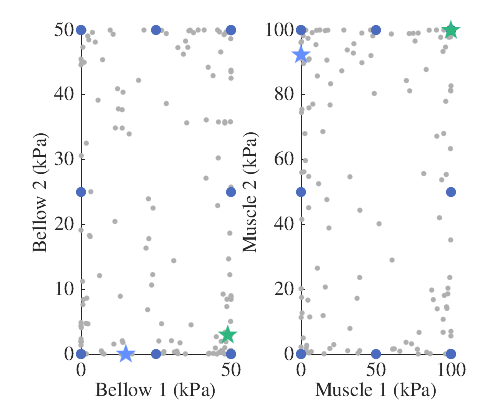

subplot(1, 2, 1);
hold on
scatter(p_interior(1, :), p_interior(4, :), 15, color_light_gray, "filled");
scatter(p_bndry(1, :), p_bndry(4, :), 50, color_dark_blue, "filled");
scatter(p_soln_min_rxn_diff(1, :), p_soln_min_rxn_diff(4, :), 250, color_yellow, 'filled', "marker", "pentagram");
scatter(p_soln_min_pose_err(1, :), p_soln_min_pose_err(4, :), 250, color_green, 'filled', "marker", "pentagram");
xlabel("Bellow 1 (kPa)")
ylabel("Bellow 2 (kPa)")
xlim([0, 50]);
ylim([0, 50]);

subplot(1, 2, 2);
hold on
scatter(p_interior(2, :), p_interior(3, :), 15, color_light_gray, "filled");
scatter(p_bndry(2, :), p_bndry(3, :), 50, color_dark_blue, "filled");
scatter(p_soln_min_rxn_diff(2, :), p_soln_min_rxn_diff(3, :), 250, color_yellow, 'filled', "marker", "pentagram");
scatter(p_soln_min_pose_err(2, :), p_soln_min_pose_err(3, :), 250, color_green, 'filled', "marker", "pentagram");
xlabel("Muscle 1 (kPa)")
ylabel("Muscle 2 (kPa)")
xlim([0, 100]);
ylim([0, 100]);

set(gcf, "Visible", true)
fontname("nimbus roman")
fontsize(15, "points")

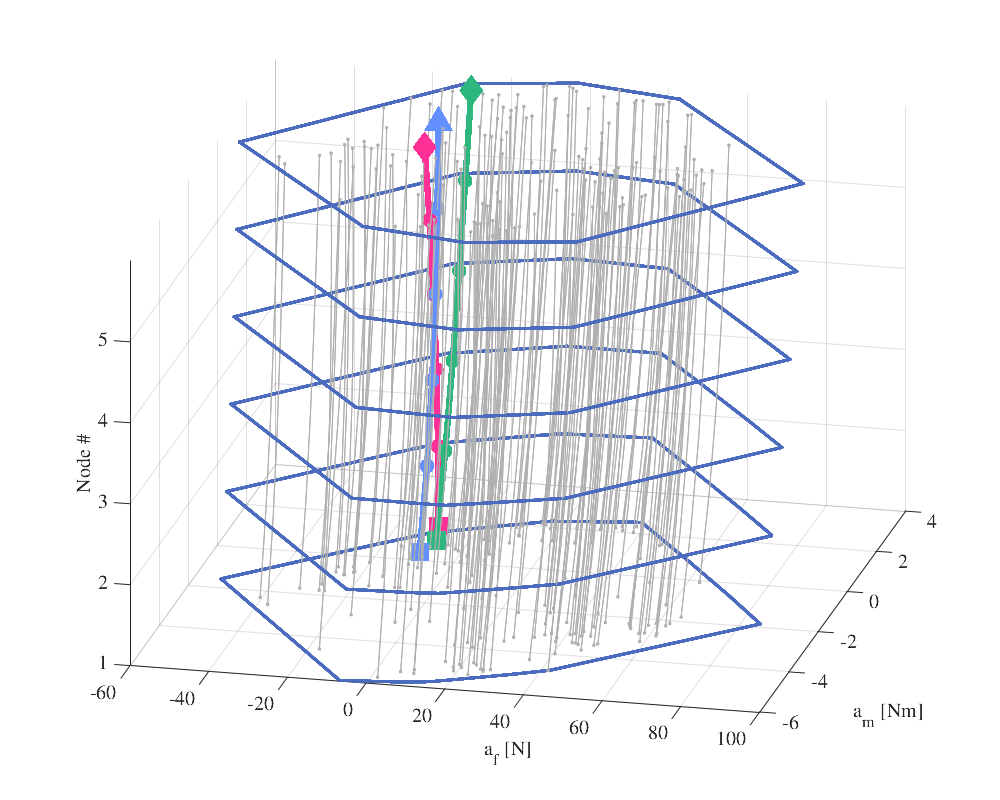

% Plot the wrench hulls. xlim([0, 50]);

lw = 4;
mksz = 12;

mat_i = repmat(transpose(1:N_nodes), 1, size(bndry_af, 2));
mat_i_samples = repmat(transpose(1:N_nodes), 1, size(interior_af, 2));

fig_wrench_hull = figure("Visible", true, "Position", [0, 0, 1000, 800], "Color", "w");
ax = axes(fig_wrench_hull);
hold on
plot_style = struct("linewidth", 2, "color", color_dark_blue);
plot_wrench_hull_loops(bndry_af, bndry_am, ax, plot_style)
%plot_wrench_hull(bndry_af_ordered, bndry_am_ordered, ax, color_blue, plot_style, (N_nodes-1));
plot3(interior_af, interior_am, mat_i_samples, "square-", "color", color_light_gray, "markerfacecolor", color_light_gray, "markersize", 2, "linewidth", 0.5, "markerindices", [1], "HandleVisibility", "off");
plot3(interior_af, interior_am, mat_i_samples, "o-", "color", color_light_gray, "markerfacecolor", color_light_gray, "markersize", 2, "linewidth", 0.5, "markerindices", [N_nodes], "HandleVisibility", "off");

plot3(req_af', req_am', mat_i, ".-", "color", color_red, "markerfacecolor", color_red, "linewidth", lw, "markersize", mksz*0.5, "marker", "o", "displayname", "Start");
plot3(req_af', req_am', mat_i, ".-", "color", color_red, "markerfacecolor", color_red, "linewidth", lw, "markersize", mksz, "markerindices", [1], "marker", "square", "displayname", "Start");
plot3(req_af', req_am', mat_i, ".-", "color", color_red, "markerfacecolor", color_red, "linewidth", lw, "markersize", mksz, "markerindices", [N_nodes], "marker", "diamond", "displayname", "End");
%plot3(closest_af', closest_am', s*(N_nodes - 1), ".-", "color", color_blue, "MarkerIndices",[1, N_nodes], "linewidth", 1.5, "markersize", 20);

plot3(closest_af_min_rxn_diff', closest_am_min_rxn_diff', mat_i, ".-", "color", color_yellow, "markerfacecolor", color_yellow, "linewidth", lw, "markersize", mksz*0.5, "marker", "o", "handlevisibility", "off");
plot3(closest_af_min_rxn_diff', closest_am_min_rxn_diff', mat_i, ".-", "color", color_yellow, "markerfacecolor", color_yellow, "linewidth", lw, "markersize", mksz, "markerindices", [1], "marker", "square", "handlevisibility", "off");
plot3(closest_af_min_rxn_diff', closest_am_min_rxn_diff', mat_i, ".-", "color", color_yellow, "markerfacecolor", color_yellow, "linewidth", lw, "markersize", mksz, "markerindices", [N_nodes], "marker", "^", "handlevisibility", "off");

plot3(closest_af_min_pose_err', closest_am_min_pose_err', mat_i, ".-", "color", color_green, "markerfacecolor", color_green, "linewidth", lw, "markersize", mksz*0.5, "marker", "o", "handlevisibility", "off");
plot3(closest_af_min_pose_err', closest_am_min_pose_err', mat_i, ".-", "color", color_green, "markerfacecolor", color_green, "linewidth", lw, "markersize", mksz, "markerindices", [1], "marker", "square", "handlevisibility", "off");
plot3(closest_af_min_pose_err', closest_am_min_pose_err', mat_i, ".-", "color", color_green, "markerfacecolor", color_green, "linewidth", lw, "markersize", mksz, "markerindices", [N_nodes], "marker", "diamond", "handlevisibility", "off")

view(13, 27)
grid on
zticks(s * (N_nodes - 1));
xlabel("a_f [N]");
ylabel("a_m [Nm]");
zlabel("Node #");
fontname("nimbus roman")
fontsize(15, "points")

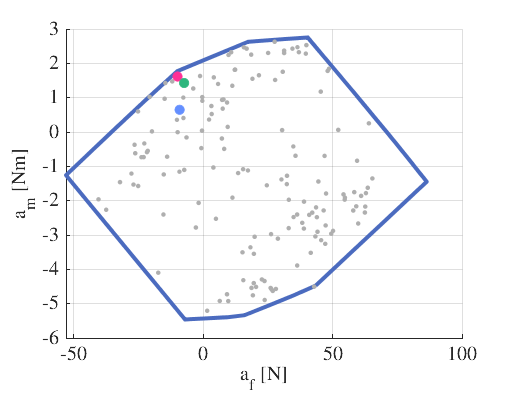

% Single cross-section view

i_cross_section = 2;

fig_cross_section = figure("Visible", true, "Position", [0, 0, 500, 400], "Color", "w");
hold on
plot(bndry_af_ordered(i_cross_section, :), bndry_am_ordered(i_cross_section, :), "color", color_dark_blue, "linewidth", 3);
plot(interior_af(i_cross_section, :), interior_am(i_cross_section, :), ".","color", color_light_gray, "linewidth", 0.5, "markersize", 10);

plot(req_af(i_cross_section, :), req_am(i_cross_section, :), "o", "color", color_red, "markerfacecolor", color_red, "markersize", 7);
plot(closest_af_min_rxn_diff(i_cross_section, :), closest_am_min_rxn_diff(i_cross_section, :), "o", "color", color_yellow, "markerfacecolor", color_yellow, "markersize", 7);
plot(closest_af_min_pose_err(i_cross_section, :), closest_am_min_pose_err(i_cross_section, :), "o", "color", color_green, "markerfacecolor", color_green, "markersize", 7);

grid on
xlabel("a_f [N]");
ylabel("a_m [Nm]");
fontname("nimbus roman")
fontsize(15, "points")

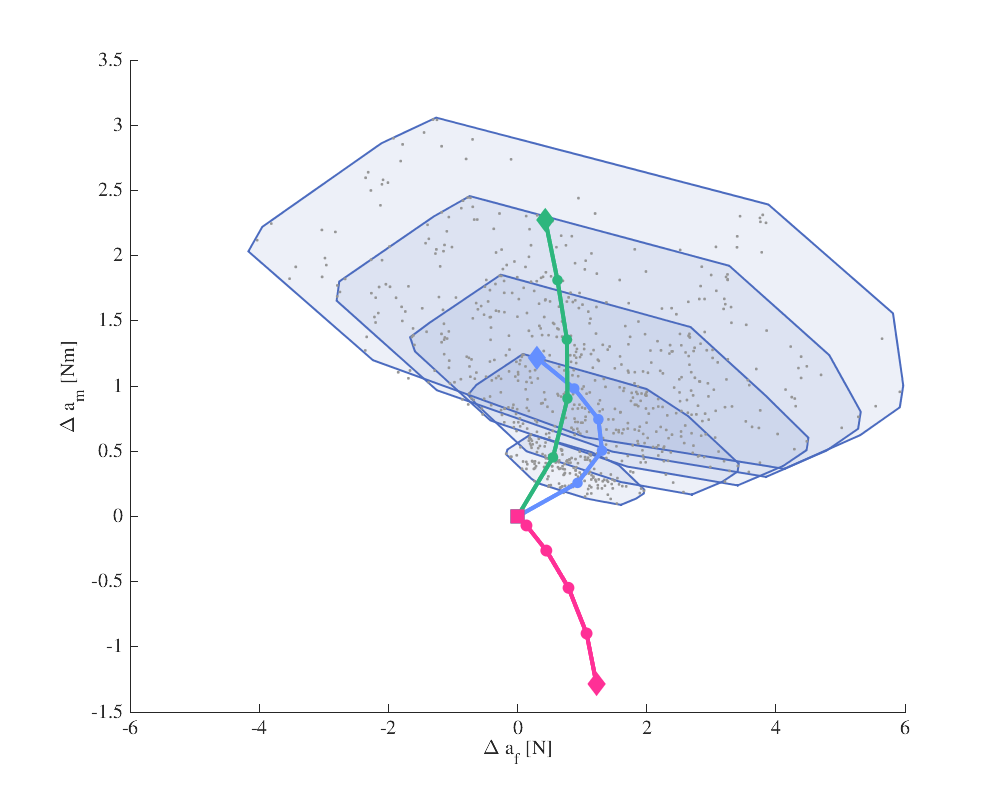


% Compute the relative wrench hulls
rltv_bndry_af = bndry_af - bndry_af(1, :);
rltv_bndry_am = bndry_am - bndry_am(1, :);

rltv_closest_af_min_rxn_diff = closest_af_min_rxn_diff - closest_af_min_rxn_diff(1);
rltv_closest_am_min_rxn_diff = closest_am_min_rxn_diff - closest_am_min_rxn_diff(1);

rltv_closest_af_min_pose_err = closest_af_min_pose_err- closest_af_min_pose_err(1);
rltv_closest_am_min_pose_err = closest_am_min_pose_err - closest_am_min_pose_err(1);

% Plot everything
fig_rltv_wrench_hull = figure("Visible", true, "Position", [0, 0, 1000, 800], "Color", "w");
ax = axes(fig_rltv_wrench_hull);
hold on
for i = 2 : N_nodes
    i_bndry = boundary(rltv_bndry_af(i, :)', rltv_bndry_am(i, :)', 0);
    fill(ax, rltv_bndry_af(i, i_bndry), rltv_bndry_am(i, i_bndry), color_dark_blue, "facealpha", 0.1, "linewidth", 1.5, "edgecolor", color_dark_blue);
end

plot(interior_rltv_af, interior_rltv_am, ".", "color", color_gray);

plot(rltv_closest_af_min_rxn_diff, rltv_closest_am_min_rxn_diff, ".-", "color", color_yellow, "linewidth", 2, "markersize", 20);
plot(rltv_closest_af_min_rxn_diff, rltv_closest_am_min_rxn_diff, ".-", "color", color_yellow, "markerfacecolor", color_yellow, "linewidth", 3, "markersize", 10, "markerindices", 1, "marker", "square");
plot(rltv_closest_af_min_rxn_diff, rltv_closest_am_min_rxn_diff, ".-", "color", color_yellow, "markerfacecolor", color_yellow, "linewidth", 3, "markersize", 10, "markerindices", N_nodes, "marker", "diamond");

plot(rltv_closest_af_min_pose_err, rltv_closest_am_min_pose_err, ".-", "color", color_green, "linewidth", 2, "markersize", 20);
plot(rltv_closest_af_min_pose_err, rltv_closest_am_min_pose_err, ".-", "color", color_green, "markerfacecolor", color_green, "linewidth", 3, "markersize", 10, "markerindices", 1, "marker", "square");
plot(rltv_closest_af_min_pose_err, rltv_closest_am_min_pose_err, ".-", "color", color_green, "markerfacecolor", color_green, "linewidth", 3, "markersize", 10, "markerindices", N_nodes, "marker", "diamond");

plot(rltv_req_af, rltv_req_am, ".-", "color", color_red, "linewidth", 3, "markersize", 20);
plot(rltv_req_af, rltv_req_am, ".-", "color", color_red, "markerfacecolor", color_red, "linewidth", 3, "markersize", 10, "markerindices", 1, "marker", "square");
plot(rltv_req_af, rltv_req_am, ".-", "color", color_red, "markerfacecolor", color_red, "linewidth", 3, "markersize", 10, "markerindices", N_nodes, "marker", "diamond");

xlabel("\Delta a_f [N]")
ylabel("\Delta a_m [Nm]")
fontname("nimbus roman")
fontsize(15, "points")

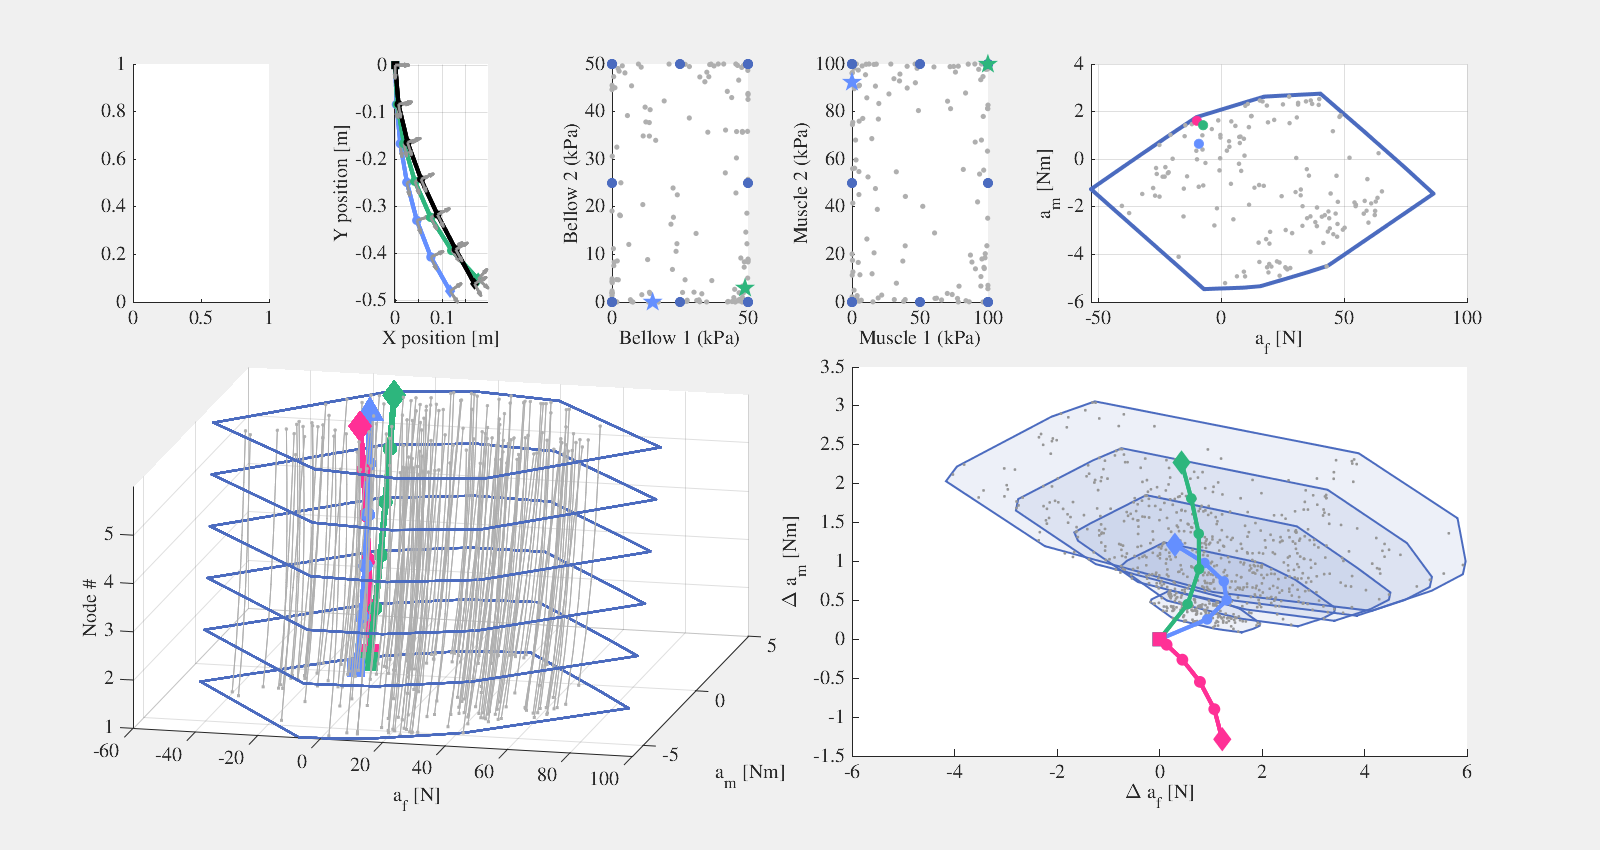

figure("Visible", true, "Position", [0, 0, 1600, 850]);
tiledlayout(5, 6, "tilespacing", "tight");

% Blank
nexttile([2, 1]);

% ========= Plot the target arm shape vs closest found shapes =========
ax = nexttile([2, 1]);
struct_closest_rxn_style = struct( ...
    "color", color_yellow, ...
    "markerfacecolor", color_yellow, ...
    "linestyle", "-", ...
    "linewidth", 3, ...
    "marker", "o", ...
    "markersize", 4, ...
    "markerindices", 2:N_nodes ...
);
struct_closest_pose_style = struct_closest_rxn_style;
struct_closest_pose_style.markerfacecolor = color_green;
struct_closest_pose_style.color= color_green;

plot_poses(poses_soln_min_rxn_diff, ax, struct_closest_rxn_style, true, "axis_length", 0.15, "pose_markers_colored", false);
struct_closest_rxn_style.marker="square";
struct_closest_rxn_style.markerindices=1;
plot_poses(poses_soln_min_rxn_diff, ax, struct_closest_rxn_style, true, "axis_length", 0.15, "pose_markers_colored", false);
struct_closest_rxn_style.marker="diamond";
struct_closest_rxn_style.markerindices=N_nodes+1;
plot_poses(poses_soln_min_rxn_diff, ax, struct_closest_rxn_style, true, "axis_length", 0.15, "pose_markers_colored", false);

plot_poses(poses_soln_min_pose_err, ax, struct_closest_pose_style, true, "axis_length", 0.15, "pose_markers_colored", false);
struct_closest_pose_style.marker="square";
struct_closest_pose_style.markerindices=1;
plot_poses(poses_soln_min_pose_err, ax, struct_closest_pose_style, true, "axis_length", 0.15, "pose_markers_colored", false);
struct_closest_pose_style.marker="diamond";
struct_closest_pose_style.markerindices=N_nodes+1;
plot_poses(poses_soln_min_pose_err, ax, struct_closest_pose_style, true, "axis_length", 0.15, "pose_markers_colored", false);


plot_poses(poses, ax, struct("linewidth", 3, "markersize", 3, "color", "k", "marker", "o", "markerfacecolor", "k", "markerindices", 2:N_nodes), true, "axis_length", 0.15, "pose_markers_colored", false);
plot_poses(poses, ax, struct("linewidth", 3, "markersize", 3, "color", "k", "marker", "square", "markerindices", 1, "markerfacecolor", "k"), true, "axis_length", 0.15, "pose_markers_colored", false);
plot_poses(poses, ax, struct("linewidth", 3, "markersize", 3, "color", "k", "marker", "diamond", "markerindices", N_nodes+1, "markerfacecolor", "k"), true, "axis_length", 0.15, "pose_markers_colored", false);

 
axis image
grid on
xlabel("X position [m]")
ylabel("Y position [m]")
fontname("nimbus roman")
fontsize(15, "points")

% ========= Pressure space =========
nexttile([2, 1]);
hold on
scatter(p_interior(1, :), p_interior(4, :), 15, color_light_gray, "filled");
scatter(p_bndry(1, :), p_bndry(4, :), 50, color_dark_blue, "filled");
scatter(p_soln_min_rxn_diff(1, :), p_soln_min_rxn_diff(4, :), 250, color_yellow, 'filled', "marker", "pentagram");
scatter(p_soln_min_pose_err(1, :), p_soln_min_pose_err(4, :), 250, color_green, 'filled', "marker", "pentagram");
xlabel("Bellow 1 (kPa)")
ylabel("Bellow 2 (kPa)")
xlim([0, 50]);
ylim([0, 50]);

nexttile([2, 1]);
hold on
scatter(p_interior(2, :), p_interior(3, :), 15, color_light_gray, "filled");
scatter(p_bndry(2, :), p_bndry(3, :), 50, color_dark_blue, "filled");
scatter(p_soln_min_rxn_diff(2, :), p_soln_min_rxn_diff(3, :), 250, color_yellow, 'filled', "marker", "pentagram");
scatter(p_soln_min_pose_err(2, :), p_soln_min_pose_err(3, :), 250, color_green, 'filled', "marker", "pentagram");
xlabel("Muscle 1 (kPa)")
ylabel("Muscle 2 (kPa)")
xlim([0, 100]);
ylim([0, 100]);

fontname("nimbus roman")
fontsize(15, "points")

% ========= Single slice view =========
nexttile([2, 2]);
i_cross_section = 2;

hold on
plot(bndry_af_ordered(i_cross_section, :), bndry_am_ordered(i_cross_section, :), "color", color_dark_blue, "linewidth", 3);
plot(interior_af(i_cross_section, :), interior_am(i_cross_section, :), ".","color", color_light_gray, "linewidth", 0.5, "markersize", 10);

plot(req_af(i_cross_section, :), req_am(i_cross_section, :), "o", "color", color_red, "markerfacecolor", color_red, "markersize", 7);
plot(closest_af_min_rxn_diff(i_cross_section, :), closest_am_min_rxn_diff(i_cross_section, :), "o", "color", color_yellow, "markerfacecolor", color_yellow, "markersize", 7);
plot(closest_af_min_pose_err(i_cross_section, :), closest_am_min_pose_err(i_cross_section, :), "o", "color", color_green, "markerfacecolor", color_green, "markersize", 7);

grid on
xlabel("a_f [N]");
ylabel("a_m [Nm]");
fontname("nimbus roman")
fontsize(15, "points")

% ========= Absolute wrench hull =========
ax = nexttile([3, 3]);

lw = 4;
mksz = 12;

mat_i = repmat(transpose(1:N_nodes), 1, size(bndry_af, 2));
mat_i_samples = repmat(transpose(1:N_nodes), 1, size(interior_af, 2));

hold on
plot_style = struct("linewidth", 1.5, "color", color_dark_blue);
plot_wrench_hull_loops(bndry_af, bndry_am, ax, plot_style)
plot3(interior_af, interior_am, mat_i_samples, "square-", "color", color_light_gray, "markerfacecolor", color_light_gray, "markersize", 2, "linewidth", 0.5, "markerindices", [1], "HandleVisibility", "off");
plot3(interior_af, interior_am, mat_i_samples, "o-", "color", color_light_gray, "markerfacecolor", color_light_gray, "markersize", 2, "linewidth", 0.5, "markerindices", [N_nodes], "HandleVisibility", "off");

plot3(req_af', req_am', mat_i, ".-", "color", color_red, "markerfacecolor", color_red, "linewidth", lw, "markersize", mksz*0.5, "marker", "o", "displayname", "Start");
plot3(req_af', req_am', mat_i, ".-", "color", color_red, "markerfacecolor", color_red, "linewidth", lw, "markersize", mksz, "markerindices", [1], "marker", "square", "displayname", "Start");
plot3(req_af', req_am', mat_i, ".-", "color", color_red, "markerfacecolor", color_red, "linewidth", lw, "markersize", mksz, "markerindices", [N_nodes], "marker", "diamond", "displayname", "End");

plot3(closest_af_min_rxn_diff', closest_am_min_rxn_diff', mat_i, ".-", "color", color_yellow, "markerfacecolor", color_yellow, "linewidth", lw, "markersize", mksz*0.5, "marker", "o", "handlevisibility", "off");
plot3(closest_af_min_rxn_diff', closest_am_min_rxn_diff', mat_i, ".-", "color", color_yellow, "markerfacecolor", color_yellow, "linewidth", lw, "markersize", mksz, "markerindices", [1], "marker", "square", "handlevisibility", "off");
plot3(closest_af_min_rxn_diff', closest_am_min_rxn_diff', mat_i, ".-", "color", color_yellow, "markerfacecolor", color_yellow, "linewidth", lw, "markersize", mksz, "markerindices", [N_nodes], "marker", "^", "handlevisibility", "off");

plot3(closest_af_min_pose_err', closest_am_min_pose_err', mat_i, ".-", "color", color_green, "markerfacecolor", color_green, "linewidth", lw, "markersize", mksz*0.5, "marker", "o", "handlevisibility", "off");
plot3(closest_af_min_pose_err', closest_am_min_pose_err', mat_i, ".-", "color", color_green, "markerfacecolor", color_green, "linewidth", lw, "markersize", mksz, "markerindices", [1], "marker", "square", "handlevisibility", "off");
plot3(closest_af_min_pose_err', closest_am_min_pose_err', mat_i, ".-", "color", color_green, "markerfacecolor", color_green, "linewidth", lw, "markersize", mksz, "markerindices", [N_nodes], "marker", "diamond", "handlevisibility", "off")

view(13, 27)
grid on
zticks(s * (N_nodes - 1));
xlabel("a_f [N]");
ylabel("a_m [Nm]");
zlabel("Node #");
fontname("nimbus roman")
fontsize(15, "points")

%  =========Relative wrench hull =========
ax = nexttile([3, 3]);
rltv_bndry_af = bndry_af - bndry_af(1, :);
rltv_bndry_am = bndry_am - bndry_am(1, :);

rltv_closest_af_min_rxn_diff = closest_af_min_rxn_diff - closest_af_min_rxn_diff(1);
rltv_closest_am_min_rxn_diff = closest_am_min_rxn_diff - closest_am_min_rxn_diff(1);

rltv_closest_af_min_pose_err = closest_af_min_pose_err- closest_af_min_pose_err(1);
rltv_closest_am_min_pose_err = closest_am_min_pose_err - closest_am_min_pose_err(1);

% Plot everything
hold on
for i = 2 : N_nodes
    i_bndry = boundary(rltv_bndry_af(i, :)', rltv_bndry_am(i, :)', 0);
    fill(ax, rltv_bndry_af(i, i_bndry), rltv_bndry_am(i, i_bndry), color_dark_blue, "facealpha", 0.1, "linewidth", 1.5, "edgecolor", color_dark_blue);
end

plot(interior_rltv_af, interior_rltv_am, ".", "color", color_gray);

plot(rltv_closest_af_min_rxn_diff, rltv_closest_am_min_rxn_diff, ".-", "color", color_yellow, "linewidth", 2, "markersize", 20);
plot(rltv_closest_af_min_rxn_diff, rltv_closest_am_min_rxn_diff, ".-", "color", color_yellow, "markerfacecolor", color_yellow, "linewidth", 3, "markersize", 10, "markerindices", 1, "marker", "square");
plot(rltv_closest_af_min_rxn_diff, rltv_closest_am_min_rxn_diff, ".-", "color", color_yellow, "markerfacecolor", color_yellow, "linewidth", 3, "markersize", 10, "markerindices", N_nodes, "marker", "diamond");

plot(rltv_closest_af_min_pose_err, rltv_closest_am_min_pose_err, ".-", "color", color_green, "linewidth", 2, "markersize", 20);
plot(rltv_closest_af_min_pose_err, rltv_closest_am_min_pose_err, ".-", "color", color_green, "markerfacecolor", color_green, "linewidth", 3, "markersize", 10, "markerindices", 1, "marker", "square");
plot(rltv_closest_af_min_pose_err, rltv_closest_am_min_pose_err, ".-", "color", color_green, "markerfacecolor", color_green, "linewidth", 3, "markersize", 10, "markerindices", N_nodes, "marker", "diamond");

plot(rltv_req_af, rltv_req_am, ".-", "color", color_red, "linewidth", 3, "markersize", 20);
plot(rltv_req_af, rltv_req_am, ".-", "color", color_red, "markerfacecolor", color_red, "linewidth", 3, "markersize", 10, "markerindices", 1, "marker", "square");
plot(rltv_req_af, rltv_req_am, ".-", "color", color_red, "markerfacecolor", color_red, "linewidth", 3, "markersize", 10, "markerindices", N_nodes, "marker", "diamond");

xlabel("\Delta a_f [N]")
ylabel("\Delta a_m [Nm]")
fontname("nimbus roman")
fontsize(15, "points")

function [boundary_af, boundary_am] = compute_attainable_wrench_space(mat_segment_twists, struct_design)
    boundary_ps = sample_edges_of_cuboid(4, struct_design.p_bounds);
    [boundary_af, boundary_am] = compute_reaction_traces(boundary_ps, mat_segment_twists, struct_design);
end

function [cell_rltv_bndry_af_per_node, cell_rltv_bndry_am_per_node] = relative_attainable_wrench_hull(bndry_af, bndry_am)
    N_nodes = size(bndry_af, 1);

    cell_rltv_bndry_af_per_node = cell(1, N_nodes);
    cell_rltv_bndry_am_per_node = cell(1, N_nodes);

    cell_rltv_bndry_af_per_node{1} = [0, 0];
    cell_rltv_bndry_am_per_node{1} = [0, 0];

    % Compute all the relative attainble reaction traces
    % These points will form the boundary of the relatively attainable
    % reaction space for each node. 
    rltv_bndry_af = bndry_af - bndry_af(1, :);
    rltv_bndry_am = bndry_am - bndry_am(1, :);

    for i = 2 : N_nodes
        % Order the points for each node, and only keep the ones that
        % contribute to the convex hull
        i_bndry = boundary(rltv_bndry_af(i, :)', rltv_bndry_am(i, :)', 0);

        cell_rltv_bndry_af_per_node{i} = rltv_bndry_af(i, i_bndry);
        cell_rltv_bndry_am_per_node{i} = rltv_bndry_am(i, i_bndry);
    end
end